clear all;

u= readtable('ctrl_inputs.csv');

x= readtable('states.csv');
time= readtable('time.csv');

kappa_opt= readtable('kappa_opt.csv');

kappa_cen= readtable('kappa_center.csv');

path_og= readtable('track_smooth.csv');

path_opt= readtable('traj_opt.csv');

s_og= readtable('length_center.csv');

s_opt= readtable('length_opt.csv');

bound_outer=readtable('bound_outer.csv');

bound_inner=readtable('bound_inner.csv');


path_shortest= readtable('traj_shortest.csv');

close all;
num_start=1;
num_end= length(s_opt.x_S_opt)-1;
plot_num= num_start:num_end;

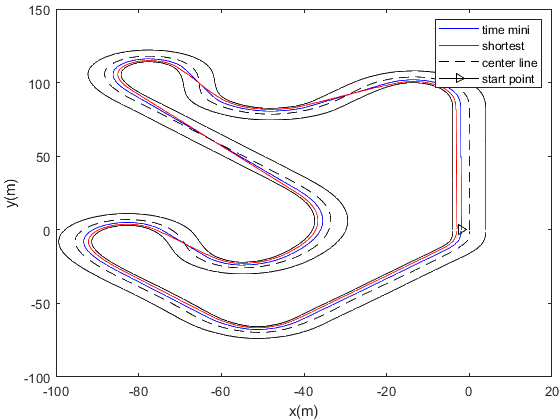

figure();
close;
plot(path_opt.x_Traj_x(plot_num), path_opt.traj_y(plot_num), 'blue', "LineWidth", 0.5)
hold on
plot(path_shortest.x_Traj_x(plot_num), path_shortest.traj_y(plot_num), 'red', "LineWidth", 0.5)
hold on
plot(path_og.x_Track_x(plot_num), path_og.track_y(plot_num), 'black', "LineWidth", 0.5, "LineStyle","--")
hold on;
plot(path_opt.x_Traj_x(1), path_opt.traj_y(1), 'black', "marker",">")
hold on;
plot(bound_outer.x_Outer_x, bound_outer.outer_y, 'black', 'LineWidth', 0.7)
hold on;
plot(bound_inner.x_Inner_x, bound_inner.inner_y, 'black','LineWidth', 0.7)
hold off;

%grid on; grid minor; 
legend('time mini', 'shortest', 'center line', 'start point',  "Location", 'Northeast')
xlabel('x(m)');
ylabel('y(m)');
set(gca,'LooseInset',get(gca,'TightInset'))

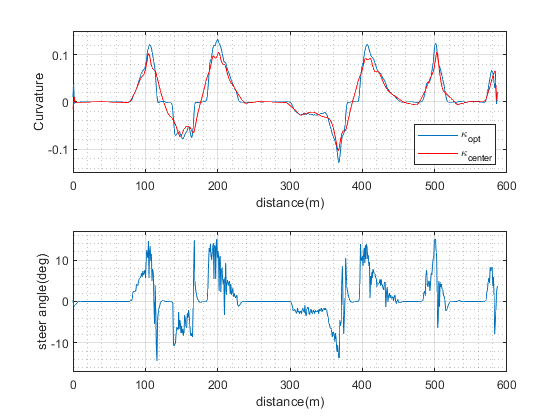

s_cumsum= cumsum(s_opt.x_S_opt);

figure;
subplot(2,1,1)
plot(s_cumsum(plot_num),kappa_opt.x_Kappa_opt(plot_num))
hold on;
plot(s_cumsum(plot_num),kappa_cen.x_Kappa_center(plot_num),'red')
hold off;
grid on; grid minor;
legend('\kappa_{opt}', '\kappa_{center}', "Location", 'Southeast')
xlim([0,600])
ylim([-0.15, 0.15])
xlabel('distance(m)')
ylabel('Curvature')

subplot(2,1,2)
plot(s_cumsum(plot_num),u.x_Delta(plot_num)*(180/pi))
grid on; grid minor;
xlim([0,600])
ylim([-17, 17])
xlabel('distance(m)')
ylabel('steer angle(deg)')